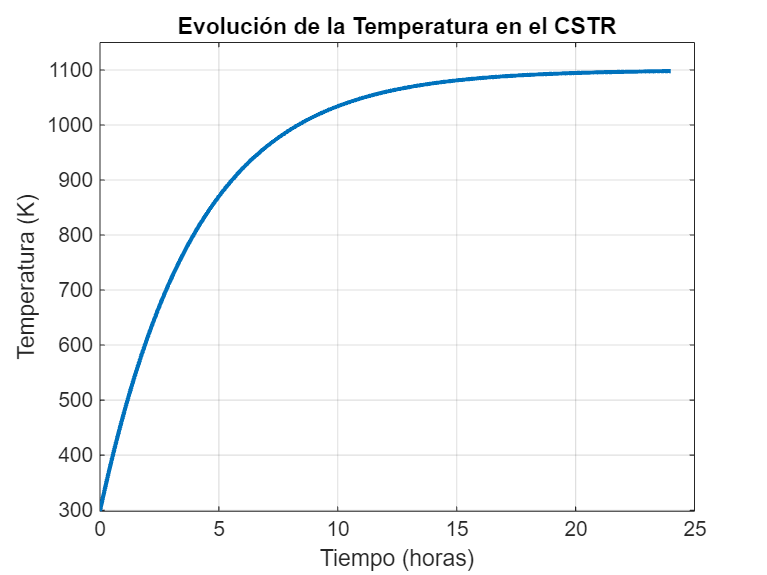

clc; clear; close all;

%% Parámetros generales
R = 8.314;         % J/(mol·K) - Constante de gases ideales
P = 1.01325;       % bar - Presión total
T_in = 298;        % K - Temperatura de entrada
T_ss = 1100;       % K - Temperatura de estado estable

% Parámetros de la reacción 1: C + CO2 -> 2 CO
A = 3.1e6;        % s^-1 bar^-0.38 - Factor preexponencial
n = 0.38;         
Ea = 215e3;       % J/mol - Energía de activación
P_CO2_init = 0.738 / 157.67;  % Fracción inicial de CO2

% Propiedades térmicas
Cp_m = 37.1;      % J/mol·K - Capacidad calorífica de CO2
Hf_CO2 = -393509e-6;  % kJ/mol -> J/mol
Hf_CO = -110525e-6;   % kJ/mol -> J/mol
DeltaH_rxn = 2*Hf_CO - Hf_CO2;  % Entalpía de reacción en J/mol

% Datos del reactor
V = 1.0;          % m^3 - Volumen del reactor
rho = 1.8;        % kg/m^3 - Densidad (estimada)
Cp_s = 800;       % J/kg·K - Cp sólido
mdot = 0.1;       % kg/s - Caudal másico de entrada

%% Cálculo de la cinética en estado estable
k_ss = A * P_CO2_init^n * exp(-Ea / (R * T_ss)); % Velocidad de reacción en T_ss

%% Balance de energía en estado estable
Q_rxn = DeltaH_rxn * k_ss * V;  % Término de generación de calor
Q_flow = mdot * Cp_s * (T_in - T_ss);  % Flujo de calor por entrada/salida

% Verificar equilibrio energético
Q_balance = Q_rxn + Q_flow;

%% Linealización para función de transferencia
tau = (rho * Cp_s * V) / mdot / 3600;  % Constante de tiempo térmica en horas
Kp = (DeltaH_rxn * V * A * P_CO2_init^n * exp(-Ea / (R * T_ss))) / (mdot * Cp_s);  % Ganancia

% Función de transferencia G(s) = Kp / (tau*s + 1)
s = tf('s');
G = Kp / (tau * s + 1);

%% Simulación de la respuesta de temperatura en el tiempo
t = linspace(0, 24 , 1000); % Tiempo en horas
T_response = T_ss + (T_in - T_ss) * exp(-t / tau);

% Graficar la evolución de la temperatura
figure;
plot(t, T_response, 'LineWidth', 2);
title('Evolución de la Temperatura en el CSTR');
xlabel('Tiempo (horas)');
ylabel('Temperatura (K)');
grid on;
ylim([T_in T_ss + 50]);

G

G =
 
  5.368e-08
  ---------
   4 s + 1
 
Continuous-time transfer function.
Model Properties


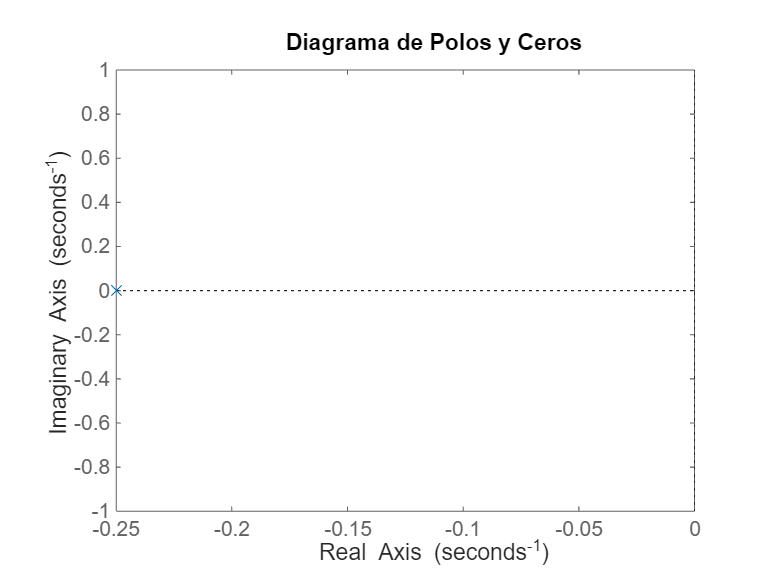

% Diagrama de polos y ceros
figure;
pzmap(G);
title('Diagrama de Polos y Ceros');


% Sintonización del control PID
Kp = 2e8; Ki = 1e8; Kd = 1e-3; % Ajuste para estabilización en 0.8
PID = pid(Kp, Ki, Kd);
G_PID = feedback(PID * G, 1, -1); % Ajuste para compatibilidad de tamaños

% Mostrar función de transferencia con control PID
disp('Función de transferencia con control PID:');

Función de transferencia con control PID:


G_PID

G_PID =
 
  5.368e-11 s^2 + 10.74 s + 5.368
  -------------------------------
      4 s^2 + 11.74 s + 5.368
 
Continuous-time transfer function.
Model Properties


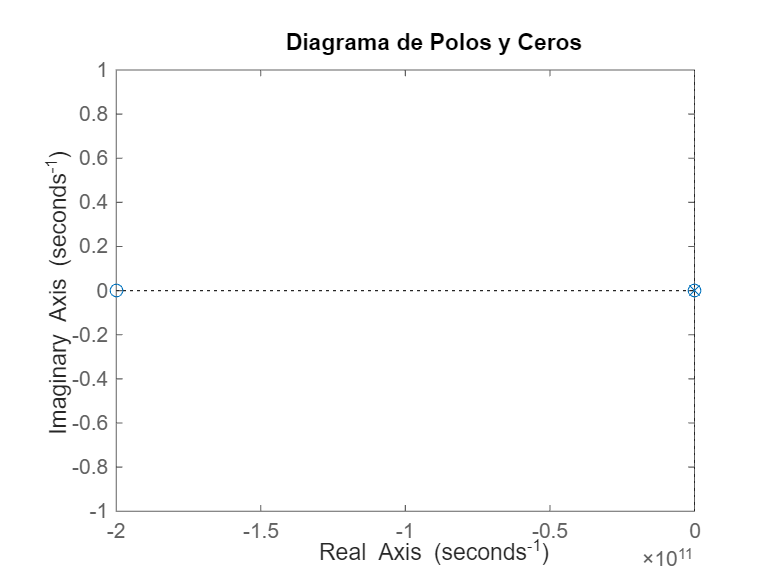

pzmap(G_PID);
title('Diagrama de Polos y Ceros');

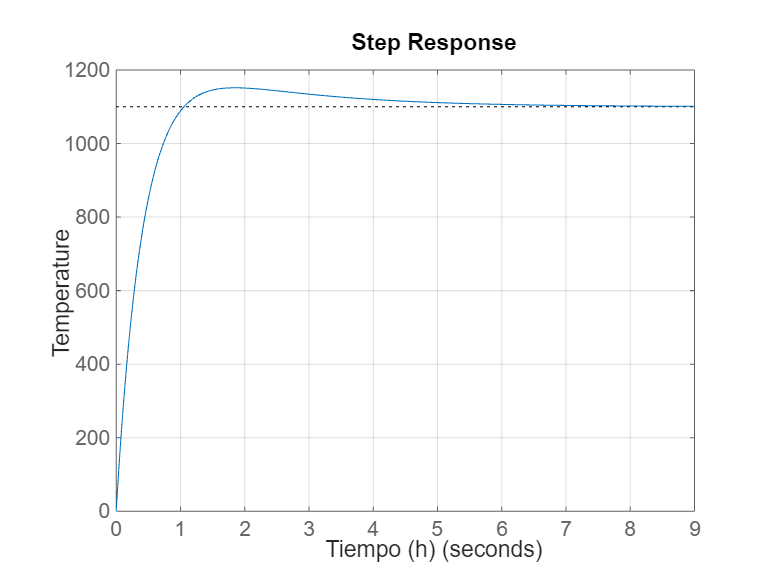


% Respuesta del sistema en lazo cerrado
y_target = 1100; % Objetivo de estabilización
figure;
step(y_target * G_PID);
xlabel('Tiempo (h)'); ylabel('Temperature');
grid on;

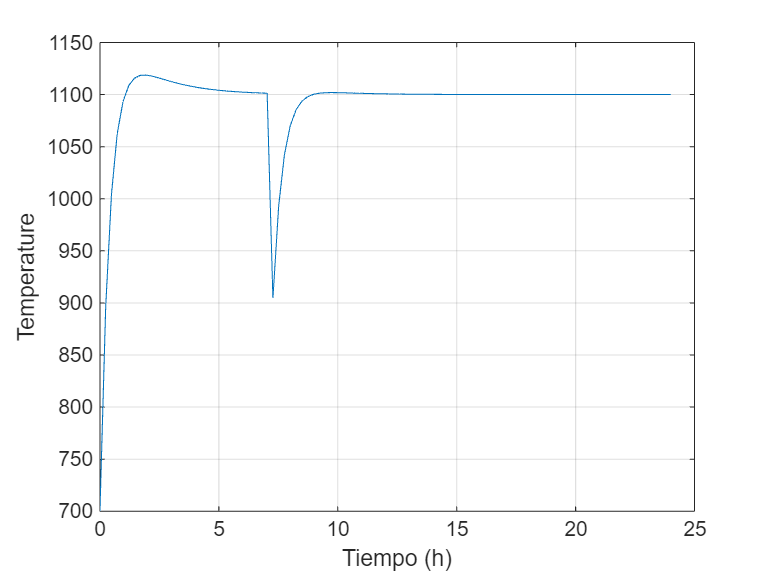


% Inserción de perturbación
t = linspace(0, 24, 100);
t_pert = t(30); % Tiempo en horas en que ocurre la perturbación
mag_pert = 400; % Magnitud de la perturbación
delta_u = zeros(size(t));
delta_u(t ~= t_pert) = mag_pert;

[y_pert, t_out] = lsim(G_PID, delta_u, t);

y_pert = y_pert - mag_pert;
figure;
plot(t_out, y_pert + y_target);
xlabel('Tiempo (h)'); ylabel('Temperature');
grid on;